# Trabajo grupal 1 (Métodos Numéricos)

- Sección: 9

- N° de grupo:  3

- Integrante 1 (líder):    Maxwell Lupo Gregorio Collazos Solis  (100%)

- Integrante 2: Pablo Nicolas Dávila Wong (100%)

- Integrante 3: Sebastian Manuel Avila Torres (100%)

- Integrante 4: Matias Fernando Castillo Quincho (100%)

- Integrante 5: Melvín Billy Leon Capcha (100%)

**Observación:** No olvidar añadir el porcentaje de participación.

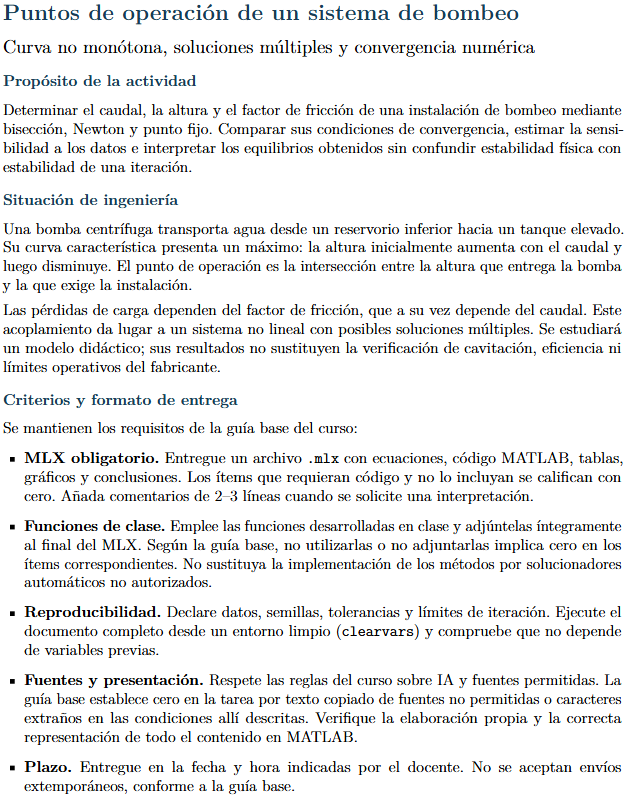

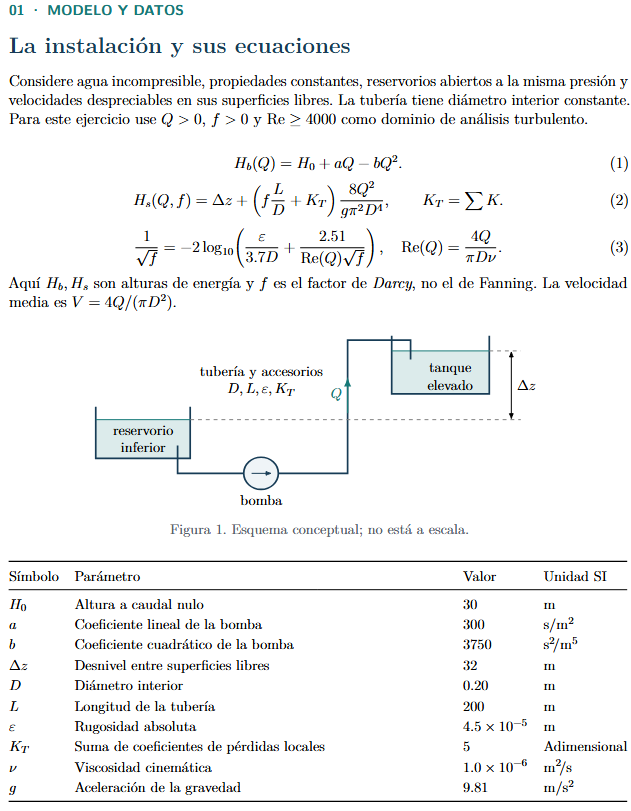

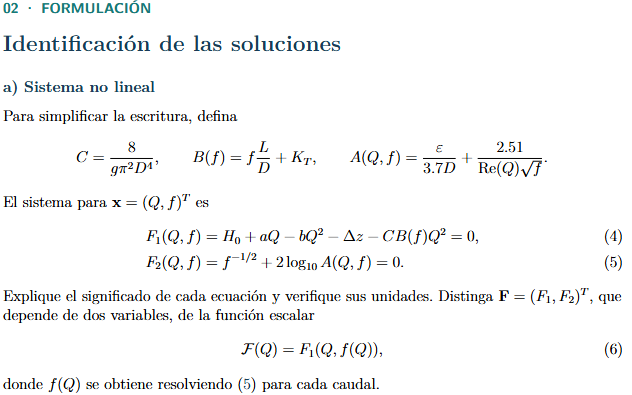

% a) SISTEMA NO LINEAL — datos, agrupaciones C, B(f), A(Q,f) y verificacion de unidades
% ==================================================================
clearvars; clc; close all;

% --- Datos del caso (Tabla del enunciado, unidades SI) ---
P.H0  = 30;        % m        Altura a caudal nulo
P.a   = 300;       % s/m^2    Coeficiente lineal de la bomba
P.b   = 3750;      % s^2/m^5  Coeficiente cuadratico de la bomba
P.dz  = 32;        % m        Desnivel entre superficies libres
P.D   = 0.20;      % m        Diametro interior
P.L   = 200;       % m        Longitud de la tuberia
P.eps = 4.5e-5;    % m        Rugosidad absoluta
P.KT  = 5;         % -        Suma de coeficientes de perdidas locales
P.nu  = 1.0e-6;    % m^2/s    Viscosidad cinematica
P.g   = 9.81;      % m/s^2    Aceleracion de la gravedad

% --- Agrupacion del enunciado ---
P.C = 8/(P.g*pi^2*P.D^4);     % s^2/m^5

% --- Escalas y referencias de los criterios (7)-(8) ---
P.Qs   = 0.01;     % m^3/s
P.fs   = 0.02;     % -
P.Href = 30;       % m

% --- Tolerancias y limites declarados (reproducibilidad) ---
tol_e   = 1e-6;    % error relativo por componente, Ec. (7)
tol_R   = 1e-8;    % residuo adimensional, Ec. (8)
tol_int = 1e-10;   % iteracion interna de f (Colebrook)
maxit_int = 100;
maxit_bis = 100;
maxit_new = 50;

% --- Verificacion de unidades ---
% F1 esta en metros:   [C*B(f)*Q^2] = (s^2/m^5)(-)(m^3/s)^2 = m
% F2 es adimensional:  [f^-1/2] = (-)  y  [A] = (-) porque
%     [eps/(3.7 D)] = m/m = -   y   [2.51/(Re sqrt(f))] = -
fprintf('Verificacion de unidades\n');
fprintf('  [C]      = s^2/m^5   -> C = %.4f\n', P.C);
fprintf('  [C*B*Q^2]= m         -> con Q=0.05, f=0.02: %.4f m\n', ...
        P.C*(0.02*P.L/P.D + P.KT)*0.05^2);
fprintf('  [A]      = adimensional (rugosidad relativa + termino de Re)\n\n');

% --- Dominio de analisis declarado ---
% Q > 0, f > 0, Re >= 4000 (turbulento) y 0 < A < 1; esta ultima condicion
% mantiene definido el logaritmo de la Ec. (5) y conserva el signo de
% Colebrook antes de elevar al cuadrado. Se verifica en dominio_ antes de
% cada evaluacion y fija el caudal minimo admisible del caso.
Qmin_dom = 4000*pi*P.D*P.nu/4;
fprintf('Dominio de analisis: Q > 0, f > 0, Re >= 4000, 0 < A < 1\n');
fprintf('  Caudal minimo turbulento: Qmin = %.6e m^3/s\n', Qmin_dom);
fprintf('  El rango de estudio [0.001, 0.08] cumple Q > Qmin.\n\n');

% Nota: F = (F1,F2)^T depende de DOS variables (Q,f); la funcion escalar
% F(Q) = F1(Q,f(Q)) depende de una sola, porque f se obtiene resolviendo
% F2(Q,f)=0 internamente para cada Q.

Significado de cada ecuación. F1 es la ecuación de energía: iguala la altura que entrega la bomba con la que exige la instalación; todos sus términos están en metros. F2 es la ecuación de Colebrook-White, que define el factor de fricción de Darcy de forma implícita y es adimensional.

Verificación de unidades. En F1, [C] = s²/m⁵, [B(f)] es adimensional y [Q²] = m⁶/s², de modo que [C·B(f)·Q²] = m, consistente con H0, ΔZ y los demás términos. En F2, [f^(-1/2)] es adimensional y el argumento del logaritmo también lo es, porque ε/(3.7D) es un cociente de longitudes y 2.51/(Re·√f) es un cociente de adimensionales.

Distinción entre F y la función escalar. F = (F1,F2)^T depende de DOS variables (Q y f), mientras que la función escalar F(Q) = F1(Q,f(Q)) depende de una sola: en ella f no es libre, sino que para cada Q se obtiene resolviendo F2(Q,f)=0 de forma interna. Por eso F(Q) sirve para graficar y localizar raíces, mientras que F1 y F2 por separado describen el sistema acoplado completo.

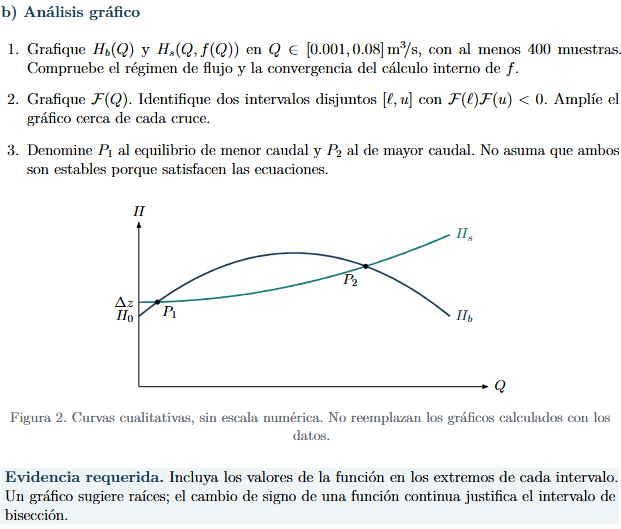

% b) ANALISIS GRAFICO — Hb, Hs, F(Q), intervalos con cambio de signo y ampliaciones
% ==================================================================
% b.1) Hb(Q) y Hs(Q,f(Q)) en [0.001, 0.08] con 500 muestras.
Q_vec  = linspace(0.001, 0.08, 500);
Re_vec = 4*Q_vec/(pi*P.D*P.nu);
f_vec  = nan(size(Q_vec));
conv_v = false(size(Q_vec));
itf_v  = zeros(size(Q_vec));

for i = 1:numel(Q_vec)
    [f_vec(i), itf_v(i), conv_v(i), ~] = friccion_pf(Q_vec(i), P, 1e-10, 100);
end

regimen_ok   = all(Re_vec >= 4000);
convergio_ok = all(conv_v);
fprintf('Regimen turbulento en todo el rango (Re >= 4000): %d  (Re_min = %.0f)\n', ...
        regimen_ok, min(Re_vec));
fprintf('Convergencia del calculo interno de f en las 500 muestras: %d  (iter max = %d)\n', ...
        convergio_ok, max(itf_v));
assert(regimen_ok && convergio_ok, 'Falla el regimen o la convergencia interna.');

Hb_vec = P.H0 + P.a*Q_vec - P.b*Q_vec.^2;
Hs_vec = P.dz + P.C*(f_vec*P.L/P.D + P.KT).*Q_vec.^2;

figure;
plot(Q_vec, Hb_vec, 'b', 'LineWidth', 2); hold on;
plot(Q_vec, Hs_vec, 'r', 'LineWidth', 2);
legend('H_b(Q) bomba','H_s(Q,f(Q)) instalacion','Location','northwest');
title('Altura entregada y altura exigida');
xlabel('Q [m^3/s]'); ylabel('H [m]'); grid on;

% b.2) F(Q) y localizacion de los dos intervalos con cambio de signo.
F_vec = Hb_vec - Hs_vec;

figure;
plot(Q_vec, F_vec, 'g', 'LineWidth', 2); hold on;
yline(0, 'k--');
title('$\mathcal{F}(Q) = H_b(Q) - H_s(Q,f(Q))$', 'Interpreter','latex');
xlabel('Q [m^3/s]'); ylabel('F(Q) [m]'); grid on;

idx = find(F_vec(1:end-1).*F_vec(2:end) < 0);
assert(numel(idx) == 2, 'Se esperaban 2 cambios de signo y se hallaron %d.', numel(idx));
intervalos = [Q_vec(idx)' Q_vec(idx+1)'];        % 2x2 : [l u] por raiz

% Evidencia requerida: valor de F en los extremos de cada intervalo.
evidencia = table( ...
    ["P1";"P1";"P2";"P2"], ...
    [intervalos(1,1); intervalos(1,2); intervalos(2,1); intervalos(2,2)], ...
    [F_vec(idx(1)); F_vec(idx(1)+1); F_vec(idx(2)); F_vec(idx(2)+1)], ...
    'VariableNames', {'Raiz','Q','F_de_Q'})

producto_signos = [F_vec(idx(1))*F_vec(idx(1)+1); F_vec(idx(2))*F_vec(idx(2)+1)];
fprintf('F(l)*F(u) = %+.4e y %+.4e  (ambos < 0: Bolzano justifica biseccion)\n', ...
        producto_signos(1), producto_signos(2));

% Ampliacion cerca de cada cruce.
for r = 1:2
    Qz = linspace(intervalos(r,1), intervalos(r,2), 150);
    Fz = arrayfun(@(q) Fesc_(q,P,1e-10,100), Qz);
    figure;
    plot(Qz, Fz, 'g', 'LineWidth', 2); hold on; yline(0,'k--');
    title(sprintf('Ampliacion cerca de P_%d', r));
    xlabel('Q [m^3/s]'); ylabel('F(Q) [m]'); grid on;
end

% b.3) Denominacion de los equilibrios.
fprintf('\nP1 = equilibrio de MENOR caudal, en [%.6f, %.6f] m^3/s\n', ...
        intervalos(1,1), intervalos(1,2));
fprintf('P2 = equilibrio de MAYOR caudal, en [%.6f, %.6f] m^3/s\n', ...
        intervalos(2,1), intervalos(2,2));
% Ambos satisfacen las ecuaciones, pero eso NO implica que ambos sean
% estables: la estabilidad fisica se decide con el signo de F'(Q_op) en
% el inciso g), no por el hecho de ser raiz.

Los dos intervalos se obtienen del cambio de signo de F(Q) sobre la malla de 500 muestras, y la tabla de evidencia reporta el valor de la función en sus extremos: en ambos casos F(l)·F(u) < 0, que es lo que justifica aplicar bisección, no el hecho de que el gráfico sugiera un cruce.

P1 es el equilibrio de menor caudal y P2 el de mayor caudal. Ambos satisfacen las ecuaciones, pero eso no implica que ambos sean estables: la estabilidad física se decide con el signo de F'(Q) en el inciso g), y se verá que sólo P2 lo es.

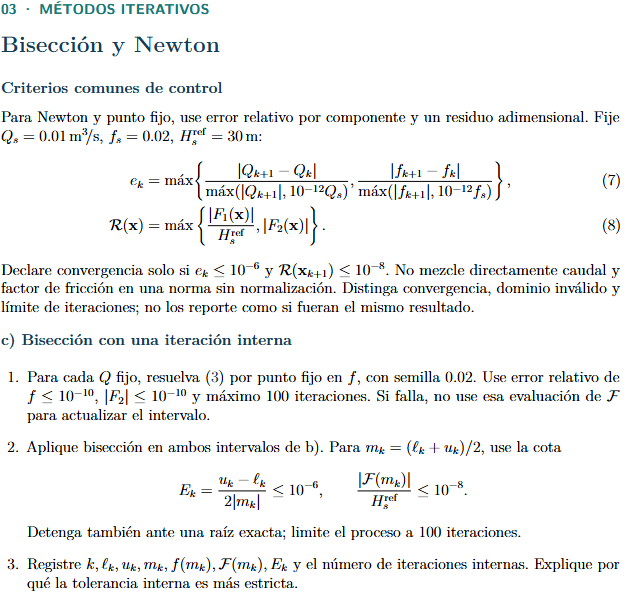

% c) BISECCION CON ITERACION INTERNA — aplicada a los DOS intervalos de b)
% ==================================================================
% Se aplica biseccion en LOS DOS intervalos hallados en b).
% La iteracion interna de f usa punto fijo con semilla 0.02 y tol 1e-10;
% si falla, esa evaluacion de F no se usa para actualizar el intervalo.

assert(exist('intervalos','var')==1, ...
    'Ejecute antes la celda b): debe existir la matriz "intervalos" (2x2).');

nombres  = ["P1"; "P2"];
raiz_bis = zeros(2,1);
fbis     = zeros(2,1);
iter_bis = zeros(2,1);
evals_bis= zeros(2,1);
estado_bis = strings(2,1);
Tbis     = cell(2,1);

for r = 1:2
    l = intervalos(r,1);  u = intervalos(r,2);
    fprintf('\n--- Biseccion en %s, intervalo [%.6f, %.6f] ---\n', nombres(r), l, u);
    [m,T,salida,nEv] = biseccion_rc(l,u,P,1e-6,1e-8,maxit_bis);
    Tbis{r}       = T;
    raiz_bis(r)   = m;
    iter_bis(r)   = height(T);
    evals_bis(r)  = nEv;
    estado_bis(r) = salida;
    if ~isempty(T), fbis(r) = T.f_m(end); else, fbis(r) = NaN; end
    fprintf('  Estado: %s | iteraciones: %d | evaluaciones de F: %d\n', ...
            salida, iter_bis(r), nEv);
    fprintf('  Raiz: Q = %.10f m^3/s , f = %.10f\n', raiz_bis(r), fbis(r));
    disp(T)
end

Tabla_biseccion = table(nombres, raiz_bis, fbis, iter_bis, evals_bis, estado_bis, ...
    'VariableNames', {'Raiz','Q','f','Iteraciones','EvalF','Estado'})

% Por que la tolerancia interna es mas estricta:
% el valor f(Q) del punto fijo entra en F(Q), que es la funcion sobre la
% que se aplica biseccion. Un error en f se propaga a F y puede alterar su
% SIGNO cerca de la raiz, provocando una actualizacion incorrecta del
% intervalo. Con tol interna 1e-10 frente a 1e-8 del residuo externo, el
% error heredado de f queda dos ordenes por debajo del criterio de parada,
% de modo que el signo de F(m) es confiable en todas las iteraciones.

Por qué la tolerancia interna es más estricta. El valor f(Q) obtenido por punto fijo entra en F(Q), que es la función sobre la que se aplica bisección. Un error en f se propaga a F y, cerca de la raíz, puede alterar su SIGNO, lo que provocaría una actualización incorrecta del intervalo. Con tolerancia interna 1e-10 frente a 1e-8 del residuo externo, el error heredado de f queda dos órdenes por debajo del criterio de parada y el signo de F(m) es confiable en todas las iteraciones.

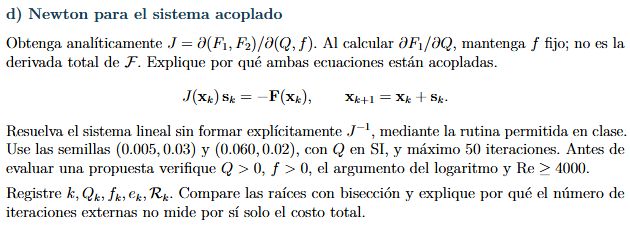

% d) NEWTON PARA EL SISTEMA ACOPLADO — Jacobiano analitico, paso sin invertir J
% ==================================================================
% Jacobiano analitico (derivadas parciales, con la otra variable FIJA):
%
%   dF1/dQ = a - 2 b Q - 2 C B(f) Q
%   dF1/df = -C (L/D) Q^2
%   dF2/dQ = -2 t / (ln10 * Q * A)                 con t = 2.51/(Re sqrt(f))
%   dF2/df = -0.5 f^(-3/2) - t / (ln10 * f * A)
%
% Acoplamiento: F1 necesita f porque las perdidas dependen de la friccion,
% y F2 necesita Q porque el numero de Reynolds depende del caudal. Ninguna
% de las dos se puede resolver aislada.

% --- Verificacion del Jacobiano con derivacion simbolica ---
syms Qv fv real
Cv  = 8/(P.g*pi^2*P.D^4);
Bv  = fv*P.L/P.D + P.KT;
Rev = 4*Qv/(pi*P.D*P.nu);
Av  = P.eps/(3.7*P.D) + 2.51/(Rev*sqrt(fv));
F1v = P.H0 + P.a*Qv - P.b*Qv^2 - P.dz - Cv*Bv*Qv^2;
F2v = 1/sqrt(fv) + 2*log10(Av);
J_sym = jacobian([F1v; F2v], [Qv, fv]);
J_num = matlabFunction(J_sym, 'Vars', {Qv, fv});
dif_J = norm(J_num(0.02,0.025) - Jac_(0.02,0.025,P), inf);
fprintf('Diferencia entre el Jacobiano analitico y el simbolico: %.3e\n', dif_J);
assert(dif_J < 1e-9, 'El Jacobiano analitico no coincide con el simbolico.');

% --- Newton desde las dos semillas del enunciado ---
semillas_N = [0.005 0.030; 0.060 0.020];
raices_N   = zeros(2,2);
iter_N     = zeros(2,1);
nF_N       = zeros(2,1);
nJ_N       = zeros(2,1);
estado_N   = strings(2,1);
TN         = cell(2,1);

for s = 1:2
    [x,T,salida,nF,nJ] = newton_rc(semillas_N(s,:)', P, tol_e, tol_R, maxit_new);
    TN{s} = T;  raices_N(s,:) = x';  estado_N(s) = salida;
    iter_N(s) = height(T)-1;  nF_N(s) = nF;  nJ_N(s) = nJ;
    fprintf('\nSemilla (Q0,f0) = (%.3f, %.3f)  ->  %s\n', ...
            semillas_N(s,1), semillas_N(s,2), salida);
    fprintf('  Q = %.10f m^3/s , f = %.10f , iteraciones externas = %d\n', ...
            x(1), x(2), iter_N(s));
    disp(T)
end

Tabla_newton = table(semillas_N(:,1), semillas_N(:,2), raices_N(:,1), raices_N(:,2), ...
    iter_N, nF_N, nJ_N, estado_N, ...
    'VariableNames', {'Q0','f0','Q','f','IterExternas','EvalF','EvalJ','Estado'})

% --- Comparacion con biseccion ---
raices_N_ord = sortrows(raices_N);
dif_metodos  = abs(raices_N_ord(:,1) - sort(raiz_bis));
Tabla_comparacion_cd = table(nombres, sort(raiz_bis), raices_N_ord(:,1), dif_metodos, ...
    'VariableNames', {'Raiz','Q_biseccion','Q_newton','Diferencia'})

% Por que las iteraciones externas no miden el costo total:
% cada iteracion de Newton evalua F, evalua J y resuelve un sistema 2x2,
% pero trabaja con (Q,f) simultaneos. Cada evaluacion de F en biseccion
% arrastra una iteracion interna completa de punto fijo sobre Colebrook
% (del orden de 7-10 pasos). Por eso hay que comparar EVALUACIONES DE
% FUNCION, no iteraciones externas: ver la tabla de sintesis final.

Por qué ambas ecuaciones están acopladas. F1 necesita f porque las pérdidas de carga dependen del factor de fricción, y F2 necesita Q porque el número de Reynolds depende del caudal. Ninguna de las dos puede resolverse de forma aislada, y por eso el Jacobiano tiene los dos términos cruzados distintos de cero.

Por qué las iteraciones externas no miden el costo total. Cada iteración de Newton evalúa F, evalúa J y resuelve un sistema 2x2, pero avanza en (Q,f) simultáneamente. En cambio, cada evaluación de F dentro de la bisección arrastra una iteración interna completa de punto fijo sobre Colebrook, del orden de 7 a 10 pasos. La comparación honesta es por evaluaciones de función, y se recoge en la tabla comparativa de la síntesis final.

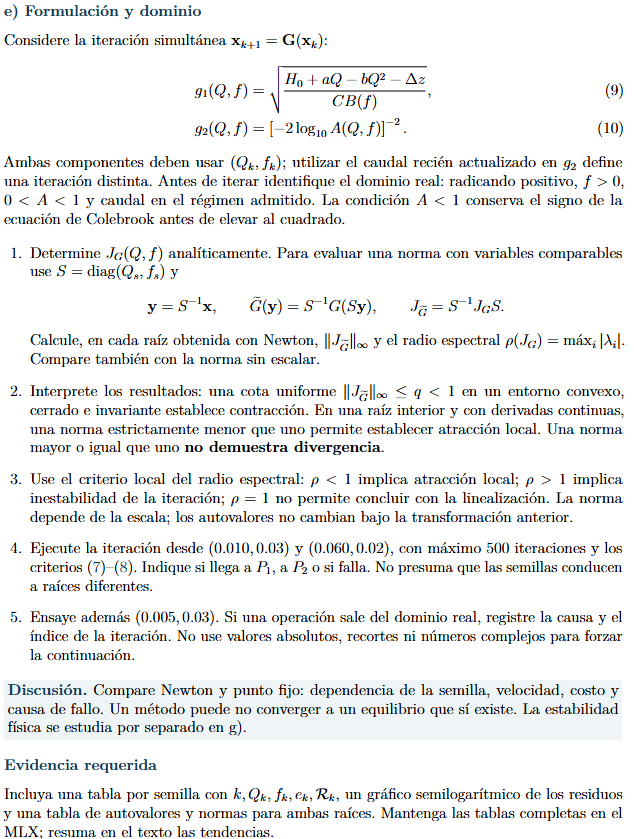

% e) FORMULACION Y DOMINIO DEL PUNTO FIJO — JG, normas, radio espectral e iteracion
% ==================================================================
% Parametros
H0 = 30; a = 300; b = 3750; delta_z = 32;       
D = 0.20; L = 200; eps = 4.5e-5; K_T = 5;
nu = 1.0e-6; g = 9.81;
C_pf = 8/(g*pi^2*D^4);
Qs_pf = 0.01; fs_pf = 0.02; Hrefs_pf = 30;
tol_e_pf = 1e-6; tol_R_pf = 1e-8; maxit_pf = 500;
 
% Abreviaciones
Re_pf = @(Q) 4*Q/(pi*D*nu);
B_pf = @(f) f*L/D + K_T;
A_pf = @(Q,f) eps/(3.7*D) + 2.51/(Re_pf(Q)*sqrt(f));
N_pf = @(Q) H0 + a*Q - b*Q^2 - delta_z; 
 
% Ecuaciones
F1_pf = @(Q,f) N_pf(Q) - C_pf*B_pf(f)*Q^2;
F2_pf = @(Q,f) 1/sqrt(f) + 2*log10(A_pf(Q,f));
R_pf  = @(Q,f) max(abs(F1_pf(Q,f))/Hrefs_pf, abs(F2_pf(Q,f)));
 
%G(X)
g1_pf = @(Q,f) sqrt(N_pf(Q)/(C_pf*B_pf(f)));
g2_pf = @(Q,f) (-2*log10(A_pf(Q,f)))^(-2);
 
%Derivadas auxiliares
%t_pf = 2.51/(Re_pf*sqrt(f))
%u_pf = -2*log10(A_pf)
%dA/dQ = -t_pf/Q
%dA/df = -t_pf/(2f)
t_pf = @(Q,f) 2.51/(Re_pf(Q)*sqrt(f));
u_pf = @(Q,f) -2*log10(A_pf(Q,f));
 
%Jacobiano analitico de G(X)
%   dg1/dQ = (a-2bQ)/(2*C_pf*B_pf*g1)      dg1/df = -g1*(L/D)/(2B)
%   dg2/dQ = -4t/(Q*u_pf^3*ln10*A_pf)      dg2/df = -2t/(f*u_pf^3*ln10*A_pf)
JG_pf = @(Q,f) [ (a-2*b*Q)/(2*C_pf*B_pf(f)*g1_pf(Q,f)),  -g1_pf(Q,f)*(L/D)/(2*B_pf(f)); ...
                 -4*t_pf(Q,f)/(Q*u_pf(Q,f)^3*log(10)*A_pf(Q,f)),  -2*t_pf(Q,f)/(f*u_pf(Q,f)^3*log(10)*A_pf(Q,f)) ];
 
%Jacobiano del sistema F(X), para obtener las raices por newton
J_pf  = @(Q,f) [ a-2*b*Q-2*C_pf*B_pf(f)*Q,  -C_pf*(L/D)*Q^2; ...
                 -2*t_pf(Q,f)/(log(10)*Q*A_pf(Q,f)),  -0.5*f^(-3/2)-t_pf(Q,f)/(log(10)*f*A_pf(Q,f)) ];
 
%Comprobacion con derivacion via syms
syms Qv fv H0_v a_v b_v dz_v D_v L_v e_v KT_v nu_v g_v positive
C_v  = 8/(g_v*pi^2*D_v^4);
B_v  = fv*L_v/D_v + KT_v;
Re_v = 4*Qv/(pi*D_v*nu_v);
A_v  = e_v/(3.7*D_v) + 2.51/(Re_v*sqrt(fv));
N_v  = H0_v + a_v*Qv - b_v*Qv^2 - dz_v;
g1_v = sqrt(N_v/(C_v*B_v));                       % ec (9)
g2_v = (-2*log10(A_v))^(-2);                      % ec (10)
F1_v = N_v - C_v*B_v*Qv^2;                        % ec (4)
F2_v = 1/sqrt(fv) + 2*log10(A_v);                 % ec (5)
 
JG_v = jacobian([g1_v; g2_v], [Qv, fv])           % Jacobiano de G(X)
J_v  = jacobian([F1_v; F2_v], [Qv, fv])           % Jacobiano de F(X)
%Valores numericos y conversion a funciones evaluables JG_v(Q,f) y J_v(Q,f)
par_v = [H0_v a_v b_v dz_v D_v L_v e_v KT_v nu_v g_v];
par_n = [H0   a   b   delta_z D   L   eps K_T nu  g  ];
JG_va = matlabFunction(subs(JG_v, par_v, par_n), 'Vars', {Qv, fv});
J_va  = matlabFunction(subs(J_v,  par_v, par_n), 'Vars', {Qv, fv});
JG_va
J_va
dif_JG_pf = norm(JG_va(0.02,0.025) - JG_pf(0.02,0.025), inf)
if dif_JG_pf<1e-15
    fprintf('Jacobiano de G verificado correctamente.\n');
else
    warning('La diferencia del Jacobiano de G supera la tolerancia.');
end
%Una vez corroborado el Jacobiano obtenido analiticamente usando el metodo de derivacion por matlab continuamos con el siguiente punto
%Las raices del inciso d) no cuadran con lo hallado en la parte a y b,
%por ello hallamos las raices usando el metodo de newton-raphson
sem_newton_pf = [0.005 0.030; 0.060 0.020];
raices_pf = zeros(2,2);
 
for s = 1:2
    xk = sem_newton_pf(s,:)';
    for k = 1:50
        sk = -J_pf(xk(1),xk(2)) \ [F1_pf(xk(1),xk(2)); F2_pf(xk(1),xk(2))];
        xk = xk + sk;
        if R_pf(xk(1),xk(2)) <= 1e-12, break, end
    end
    raices_pf(s,:) = xk';
end

raices_pf = sortrows(raices_pf);
nombres_pf = ["P1"; "P2"];
raices_pf
%Jacobiano de G en cada raiz: normas y radio espectral
S_pf = diag([Qs_pf fs_pf]);
rho_pf = zeros(2,1); nEsc_pf = zeros(2,1); nSin_pf = zeros(2,1);
lam_pf = zeros(2,2); difev_pf = zeros(2,1);
 
for r = 1:2
    JGr = JG_pf(raices_pf(r,1), raices_pf(r,2));
    JGe = S_pf \ JGr * S_pf;                     % S_pf^-1 * JG * S_pf
    ev  = eig(JGr);
    [~,ord] = sort(abs(ev),'descend');  ev = ev(ord);
    lam_pf(r,:) = ev.';
    rho_pf(r)   = max(abs(ev));
    nSin_pf(r)  = norm(JGr, inf);
    nEsc_pf(r)  = norm(JGe, inf);
    difev_pf(r) = norm(sort(abs(eig(JGe))) - sort(abs(eig(JGr))));   % autovalores no cambian con S_pf
end
 
concl_pf = strings(2,1);
for r = 1:2
    if rho_pf(r) < 1
        concl_pf(r) = "rho < 1: atraccion local";
    elseif rho_pf(r) > 1
        concl_pf(r) = "rho > 1: iteracion inestable";
    else
        concl_pf(r) = "rho = 1: no concluye";
    end
end
 
Tabla_autovalores = table(nombres_pf, raices_pf(:,1), raices_pf(:,2), lam_pf(:,1), lam_pf(:,2), ...
    rho_pf, nEsc_pf, nSin_pf, difev_pf, concl_pf, ...
    'VariableNames', {'Raiz','Q','f','lambda1','lambda2','rho', ...
    'norma_inf_escalada','norma_inf_sin_escalar','dif_autovalores','conclusion'})

%5) Iteracion de punto fijo simultanea (ambas componentes con (Qk,fk))
semillas_pf = [0.010 0.030; 0.060 0.020; 0.005 0.030];
nS_pf = size(semillas_pf,1);
tabla_pf = cell(nS_pf,1);
estado_pf = strings(nS_pf,1);  causa_pf = strings(nS_pf,1);  destino_pf = strings(nS_pf,1);
kfallo_pf = nan(nS_pf,1);  iter_pf = zeros(nS_pf,1);
Qfin_pf = zeros(nS_pf,1);  ffin_pf = zeros(nS_pf,1);  Rfin_pf = zeros(nS_pf,1);
 
for s = 1:nS_pf
    Qk = semillas_pf(s,1);  fk = semillas_pf(s,2);
    filas  = [0, Qk, fk, NaN, R_pf(Qk,fk)];
    estado = "limite de iteraciones";  causa = "-";  kfallo = NaN;
 
    for k = 0:maxit_pf-1
        causa = "-";
        if Qk <= 0
            causa = "Q <= 0";
        elseif fk <= 0
            causa = "f <= 0";
        elseif Re_pf(Qk) < 4000
            causa = "Re < 4000";
        elseif N_pf(Qk) <= 0
            causa = "radicando de g1 <= 0";
        elseif A_pf(Qk,fk) <= 0 || A_pf(Qk,fk) >= 1
            causa = "A fuera de (0,1)";
        end
        if causa ~= "-"
            estado = "dominio invalido";  kfallo = k;  break
        end
        Qn = g1_pf(Qk,fk);
        fn = g2_pf(Qk,fk);
        ek = max( abs(Qn-Qk)/max(abs(Qn),1e-12*Qs_pf), ...
            abs(fn-fk)/max(abs(fn),1e-12*fs_pf) );
        Rk = R_pf(Qn,fn);
        filas(end+1,:) = [k+1, Qn, fn, ek, Rk];
        Qk = Qn;  fk = fn;
 
        if ek <= tol_e_pf && Rk <= tol_R_pf
            estado = "convergio";  break
        end
    end
 
    %destino: solo si convergio y esta sobre P1 o P2
    [dmin, ir] = min(abs(Qk - raices_pf(:,1))./raices_pf(:,1));
    if estado == "convergio" && dmin < 1e-4
        destino = nombres_pf(ir);
    else
        destino = "ninguna";
    end
 
    tabla_pf{s}   = array2table(filas, 'VariableNames', {'k','Qk','fk','ek','Rk'});
    estado_pf(s)  = estado;   causa_pf(s) = causa;   kfallo_pf(s) = kfallo;
    destino_pf(s) = destino;  iter_pf(s)  = size(filas,1) - 1;
    Qfin_pf(s) = Qk;  ffin_pf(s) = fk;  Rfin_pf(s) = filas(end,5);
end
 
%Tablas por semilla
for s = 1:nS_pf
    fprintf('\nSemilla %d: (Q0, f0) = (%.3f, %.3f)  ->  %s', s, semillas_pf(s,1), semillas_pf(s,2), estado_pf(s));
    if estado_pf(s) == "dominio invalido"
        fprintf('  [causa: %s, en el indice k = %d]', causa_pf(s), kfallo_pf(s));
    end
    fprintf('\n');
    disp(tabla_pf{s})
end

%Grafico semilogaritmico
col_pf = lines(nS_pf);
figure; hold on; grid on
for s = 1:nS_pf
    Ts = tabla_pf{s};
    plot(Ts.k, Ts.Rk, '-o', 'MarkerSize', 3, 'Color', col_pf(s,:), ...
        'DisplayName', sprintf('semilla %d (%.3f, %.3f)', s, semillas_pf(s,1), semillas_pf(s,2)));
end
yline(tol_R_pf, 'k--', 'DisplayName', 'tolerancia R = 10^{-8}');
set(gca, 'YScale', 'log');
xlabel('k (iteracion)');  ylabel('R_k (adimensional)');
title('Residuo R_k del punto fijo');
legend('show', 'Location', 'northeast');

%Resumen por semilla
Tabla_resumen = table((1:nS_pf)', semillas_pf(:,1), semillas_pf(:,2), estado_pf, iter_pf, destino_pf, ...
    Qfin_pf, ffin_pf, Rfin_pf, causa_pf, kfallo_pf, ...
    'VariableNames', {'Semilla','Q0','f0','Estado','Iteraciones','Destino', ...
    'Q_final','f_final','R_final','Causa_fallo','k_fallo'})

En la tabla de autovalores se observa que en ambas raíces la norma infinito del Jacobiano de G(X), tanto escalada como sin escalar, es mayor que 1: 11.71 y 11.57 en P1, y 3.47 y 2.18 en P2. Por ende la norma no permite garantizar contracción en un entorno cerrado, convexo e invariante, ni atracción local en ninguno de los dos puntos. Sin embargo, una norma mayor o igual que 1 no demuestra divergencia, ya que es sólo una condición suficiente y depende de la escala S elegida.

Para poder decidir se usa el radio espectral, que no depende de la escala. En P1, ρ = 11.43 > 1, por lo que la iteración de punto fijo es inestable en ese punto: P1 es una raíz del sistema, pero G no converge a ella. En P2, ρ = 0.949 < 1, por lo que sí hay atracción local. Al estar tan cerca de 1, esa atracción es lenta, y como el autovalor dominante es negativo (-0.949) las iteraciones se acercan alternando de lado respecto de P2. Esto explica que en P2 la norma sea mayor que 1 y aun así la iteración converja localmente. El vector de diferencias de autovalores es nulo, lo que confirma que los autovalores no cambian con el escalado.

Las semillas (0.010, 0.03) y (0.060, 0.02) convergen ambas a P2, en 299 y 307 iteraciones respectivamente. Ninguna llega a P1, aunque la primera inicia más cerca de él, lo que es consistente con que P1 repele la iteración (ρ = 11.43 > 1).

La semilla (0.005, 0.03) falla en el índice k = 0 porque el radicando de g1 es negativo. Ese radicando es H0 + aQ - bQ² - Δz, expresable también como Hb(Q) - Δz, es decir, la altura de la bomba menos el desnivel. Cuando Q = 0.005, Hb(Q) = 31.41 m, menor que Δz = 32 m, y el numerador resulta -0.59. Como el denominador C·B(f) es positivo, el radicando completo también es negativo (aprox. -3.3e-4). La iteración se detiene ahí y se registra la causa, sin usar valores absolutos, recortes ni números complejos para forzar la continuación.

En el gráfico semilogarítmico el residuo baja en línea recta, es decir, la convergencia es lineal, con una tasa cercana al radio espectral de P2.

En la tabla resumen se aprecia que, con el método de punto fijo, sólo las semillas 1 y 2 convergen, ambas a P2, y se registra la causa de fallo de la semilla 3 junto con su índice de iteración final.

Discusión: Newton-Raphson frente a Punto Fijo.

Dependencia de la semilla. Newton alcanzó ambas raíces desde sus semillas correspondientes; el punto fijo sólo logró converger a P2, y ninguna semilla lo llevó a P1.

Velocidad. Newton convergió en 5 iteraciones con tasa cuadrática, frente a las aproximadamente 300 iteraciones del punto fijo, que converge linealmente con tasa cercana a ρ = 0.949 en P2.

Costo. Aunque Newton evalúa F y J y resuelve un sistema lineal de 2x2 en cada paso, mientras el punto fijo sólo evalúa g1 y g2, la diferencia en el número de iteraciones es tan grande que Newton resulta claramente más barato en total.

Causa de fallo. El punto fijo converge únicamente a P2 porque ρ(JG) > 1 en P1, y además puede salir del dominio real, como ocurre con la semilla (0.005, 0.03), cuyo radicando de g1 es negativo desde el índice k = 0.

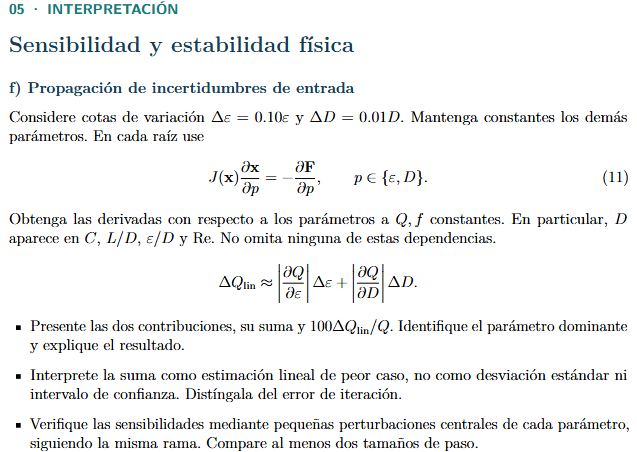

% f) PROPAGACION DE INCERTIDUMBRES DE ENTRADA — sensibilidad a eps y D
% ==================================================================
% Se resuelve  J(x) dx/dp = -dF/dp  para p en {eps, D}, con las derivadas
% respecto al parametro tomadas a Q y f CONSTANTES.
% D aparece en C (como D^-4), en L/D, en eps/D y en Re: las cuatro
% dependencias estan incluidas en dFdD_.

d_eps = 0.10*P.eps;
d_D   = 0.01*P.D;
raices = sortrows(raices_N);          % [Q f] de P1 y P2, obtenidas en d)

dQde = zeros(2,1);  dQdD = zeros(2,1);
dfde = zeros(2,1);  dfdD = zeros(2,1);
c_eps = zeros(2,1); c_D = zeros(2,1);

for r = 1:2
    Q = raices(r,1);  f = raices(r,2);
    J = Jac_(Q,f,P);
    se = J\(-dFdeps_(Q,f,P));         % dx/d(eps)
    sD = J\(-dFdD_(Q,f,P));           % dx/dD
    dQde(r) = se(1);  dfde(r) = se(2);
    dQdD(r) = sD(1);  dfdD(r) = sD(2);
    c_eps(r) = abs(dQde(r))*d_eps;    % contribucion de eps
    c_D(r)   = abs(dQdD(r))*d_D;      % contribucion de D
end

dQ_lin  = c_eps + c_D;
pct     = 100*dQ_lin./raices(:,1);
dominante = strings(2,1);
for r = 1:2
    if c_D(r) > c_eps(r), dominante(r) = "D"; else, dominante(r) = "eps"; end
end

Tabla_sensibilidad = table(nombres, raices(:,1), dQde, dQdD, c_eps, c_D, dQ_lin, pct, dominante, ...
    'VariableNames', {'Raiz','Q','dQ_deps','dQ_dD','Contrib_eps','Contrib_D', ...
                      'Suma_dQlin','Porc_dQ_Q','Dominante'})

% --- Verificacion por perturbaciones centrales, siguiendo la misma rama ---
pasos = [1e-3 1e-4];
ver = [];
for r = 1:2
    x0 = raices(r,:)';
    for h = pasos
        he = h*P.eps;  hD = h*P.D;

        Pp = P; Pp.eps = P.eps + he;  xp = newton_rc(x0,Pp,1e-12,1e-12,50);
        Pm = P; Pm.eps = P.eps - he;  xm = newton_rc(x0,Pm,1e-12,1e-12,50);
        num_e = (xp(1) - xm(1))/(2*he);

        % C = 8/(g pi^2 D^4) es un campo DERIVADO: al perturbar D hay que
        % recalcularlo, o la diferencia central pierde justamente la
        % dependencia dominante y la verificacion no valida.
        Pp = P; Pp.D = P.D + hD;  Pp.C = 8/(P.g*pi^2*Pp.D^4);
        Pm = P; Pm.D = P.D - hD;  Pm.C = 8/(P.g*pi^2*Pm.D^4);
        xp = newton_rc(x0,Pp,1e-12,1e-12,50);
        xm = newton_rc(x0,Pm,1e-12,1e-12,50);
        num_D = (xp(1) - xm(1))/(2*hD);

        ver = [ver; r h dQde(r) num_e abs(num_e-dQde(r)) ...
                        dQdD(r) num_D abs(num_D-dQdD(r))];   %#ok<AGROW>
    end
end
Tabla_verificacion_sens = array2table(ver, 'VariableNames', ...
    {'Raiz','paso_rel','dQ_deps_analitico','dQ_deps_numerico','dif_eps', ...
     'dQ_dD_analitico','dQ_dD_numerico','dif_D'})

% Interpretacion:
% D domina la sensibilidad en ambas raices, con una contribucion del orden
% de seis veces la de eps. Es consistente con que eps entra solo en A
% (efecto logaritmico y amortiguado), mientras D entra en cuatro lugares y
% el mas fuerte es C ~ D^-4, de modo que un 1% en D mueve las perdidas
% cerca de un 5%. La suma es una cota LINEAL DE PEOR CASO: supone que las
% dos desviaciones ocurren a la vez y en el sentido mas desfavorable. No
% es una desviacion estandar ni un intervalo de confianza, y es distinta
% del error de iteracion, que aqui es del orden de 1e-8 y por lo tanto
% despreciable frente a esta incertidumbre de datos.

Parámetro dominante. El diámetro D domina la sensibilidad en las dos raíces, con una contribución del orden de seis veces la de la rugosidad. Es coherente con la estructura del modelo: ε entra únicamente en A, con efecto logarítmico y muy amortiguado, mientras que D entra en cuatro lugares (C, L/D, ε/D y Re) y el más fuerte es C ~ D^(-4), de modo que una desviación del 1% en D mueve las pérdidas cerca de un 5%.

Interpretación de la suma. ΔQ_lin es una estimación lineal de PEOR CASO: supone que las dos desviaciones ocurren a la vez y en el sentido más desfavorable. No es una desviación estándar ni un intervalo de confianza. Tampoco debe confundirse con el error de iteración, que aquí es del orden de 1e-8 y resulta despreciable frente a esta incertidumbre de datos.

La verificación por perturbaciones centrales, con dos tamaños de paso distintos y siguiendo la misma rama, reproduce las sensibilidades analíticas en las primeras seis cifras significativas, lo que confirma que las derivadas respecto a los parámetros están completas.

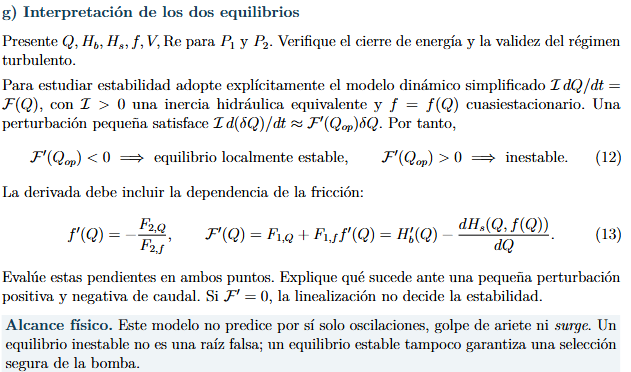

% g) INTERPRETACION DE LOS DOS EQUILIBRIOS — cierre de energia y estabilidad fisica
% ==================================================================
Qg = raices(:,1);  fg = raices(:,2);
Hb_g = zeros(2,1); Hs_g = zeros(2,1); V_g = zeros(2,1); Re_g = zeros(2,1);
cierre = zeros(2,1); Fp_g = zeros(2,1); fp_g = zeros(2,1);
estabilidad = strings(2,1);

for r = 1:2
    Hb_g(r) = Hb_(Qg(r),P);
    Hs_g(r) = Hs_(Qg(r),fg(r),P);
    cierre(r) = abs(Hb_g(r) - Hs_g(r));
    V_g(r)  = 4*Qg(r)/(pi*P.D^2);
    Re_g(r) = Re_(Qg(r),P);
    [Fp_g(r), fp_g(r)] = dF_(Qg(r),P);
    if Fp_g(r) < 0
        estabilidad(r) = "localmente estable";
    elseif Fp_g(r) > 0
        estabilidad(r) = "inestable";
    else
        estabilidad(r) = "la linealizacion no decide";
    end
end

Tabla_equilibrios = table(nombres, Qg, Hb_g, Hs_g, cierre, fg, V_g, Re_g, fp_g, Fp_g, estabilidad, ...
    'VariableNames', {'Punto','Q','Hb','Hs','Cierre_energia','f','V','Re', ...
                      'df_dQ','dF_dQ','Estabilidad'})

fprintf('Cierre de energia: |Hb-Hs| = %.2e y %.2e m  (ambos en el ruido numerico)\n', ...
        cierre(1), cierre(2));
fprintf('Regimen turbulento: Re = %.0f y %.0f, ambos >> 4000\n', Re_g(1), Re_g(2));

% Interpretacion bajo el modelo I dQ/dt = F(Q):
% En P1, F'(Q) > 0. Una perturbacion positiva de caudal hace F > 0, luego
% dQ/dt > 0 y el caudal sigue creciendo, alejandose de P1 hasta alcanzar
% P2. Una perturbacion negativa hace F < 0 y el caudal colapsa hacia el
% reposo. P1 es entonces inestable: es una raiz legitima del sistema, pero
% la instalacion no puede sostenerse en ella.
% En P2, F'(Q) < 0. Una perturbacion positiva produce F < 0, que frena el
% caudal, y una negativa produce F > 0, que lo acelera: en ambos casos el
% sistema regresa a P2. P2 es el punto de operacion localmente estable.
% Notar que la estabilidad de esta iteracion no es lo mismo que la
% estabilidad del metodo de punto fijo del inciso e): alli P2 atraia la
% iteracion por rho < 1, que es una propiedad del algoritmo, no de la
% fisica del sistema.

Comportamiento ante una perturbación. En P1 se tiene F'(Q) > 0: una perturbación positiva de caudal hace F > 0, luego dQ/dt > 0 y el caudal sigue creciendo, alejándose de P1 hasta alcanzar P2; una perturbación negativa hace F < 0 y el caudal colapsa hacia el reposo. P1 es por tanto inestable, aunque sea una raíz legítima del sistema.

En P2 se tiene F'(Q) < 0: una perturbación positiva produce F < 0, que frena el caudal, y una negativa produce F > 0, que lo acelera. En ambos casos el sistema regresa a P2, que es el punto de operación localmente estable bajo el modelo adoptado.

Conviene no confundir esta estabilidad con la del inciso e). Allí P2 atraía la iteración porque ρ(JG) < 1, que es una propiedad del ALGORITMO; aquí P2 es estable porque F'(Q) < 0, que es una propiedad FÍSICA del sistema. Que coincidan en este caso es una circunstancia, no una regla.

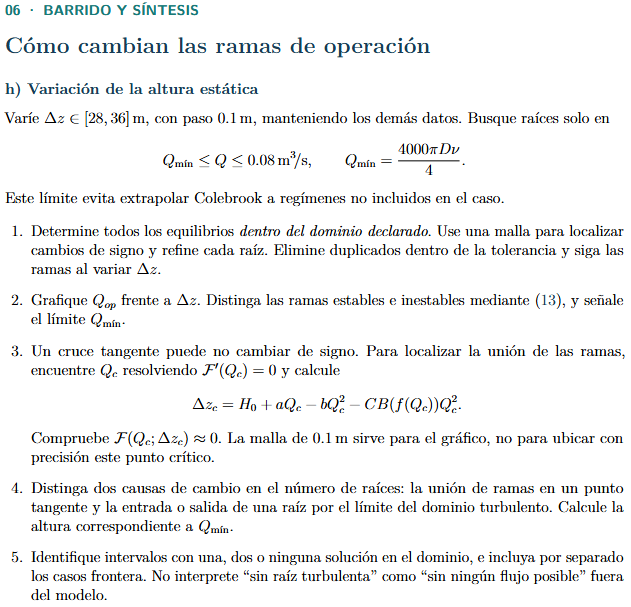

% h) VARIACION DE LA ALTURA ESTATICA — ramas, punto tangente y limite turbulento
% ==================================================================
% Como F(Q;dz) = Phi(Q) - dz, con Phi(Q) = Hb(Q) - C*B(f(Q))*Q^2
% independiente de dz, todo el barrido consiste en invertir Phi, y
% ademas F'(Q) = Phi'(Q) para cualquier dz.

Qmin = 4000*pi*P.D*P.nu/4;
fprintf('Qmin = %.6e m^3/s  (Re = %.1f)\n', Qmin, Re_(Qmin,P));

dz_vec = 28:0.1:36;
Qg_mesh = linspace(Qmin, 0.08, 4000);
Phi_mesh = arrayfun(@(q) Phi_(q,P), Qg_mesh);

% h.1-h.2) Equilibrios en cada dz y clasificacion de ramas.
res = [];                      % [dz  Q  F'(Q)  estable]
nraices = zeros(size(dz_vec));
for i = 1:numel(dz_vec)
    dz = dz_vec(i);
    G  = Phi_mesh - dz;
    id = find(G(1:end-1).*G(2:end) < 0);
    Qr = [];
    for k = 1:numel(id)
        l = Qg_mesh(id(k));  u = Qg_mesh(id(k)+1);
        for it = 1:200                        % refinamiento por biseccion
            m = (l+u)/2;
            if (Phi_(l,P)-dz)*(Phi_(m,P)-dz) < 0, u = m; else, l = m; end
            if (u-l) <= 1e-14*max(1,abs(m)), break; end
        end
        Qr(end+1) = (l+u)/2;                  %#ok<AGROW>
    end
    if ~isempty(Qr)
        Qr = uniquetol(Qr, 1e-8);             % eliminar duplicados
        for k = 1:numel(Qr)
            Fp = dF_(Qr(k),P);
            res = [res; dz Qr(k) Fp double(Fp<0)];   %#ok<AGROW>
        end
    end
    nraices(i) = numel(Qr);
end

figure; hold on; grid on;
est = res(:,4)==1;
plot(res(est,1),  res(est,2),  '.', 'Color',[0.10 0.45 0.20], 'MarkerSize', 9);
plot(res(~est,1), res(~est,2), '.', 'Color',[0.75 0.15 0.15], 'MarkerSize', 9);
yline(Qmin, 'k--', 'LineWidth', 1.2);
xlabel('\Delta z [m]'); ylabel('Q_{op} [m^3/s]');
title('Ramas de operacion frente a la altura estatica');
legend('rama estable (F'' < 0)','rama inestable (F'' > 0)','Q_{min} (Re = 4000)', ...
       'Location','northeast');

% h.3) Punto de union de las ramas: F'(Qc) = 0 (biseccion sobre F').
lc = Qmin;  uc = 0.08;
for it = 1:200
    mc = (lc+uc)/2;
    if dF_(lc,P)*dF_(mc,P) < 0, uc = mc; else, lc = mc; end
    if (uc-lc) <= 1e-15*max(1,abs(mc)), break; end
end
Qc  = (lc+uc)/2;
dzc = Phi_(Qc,P);
Pc = P; Pc.dz = dzc;
[Fqc, fqc] = Fesc_(Qc, Pc, 1e-12, 200);
fprintf('\nPunto tangente: Qc = %.10f m^3/s , dz_c = %.6f m\n', Qc, dzc);
fprintf('  Comprobacion: F(Qc; dz_c) = %.3e   y   F''(Qc) = %.3e\n', Fqc, dF_(Qc,P));

% h.4) Altura correspondiente a Qmin (salida de una raiz por el dominio).
dz_min = Phi_(Qmin,P);
fprintf('Altura en el limite turbulento: Phi(Qmin) = %.6f m\n', dz_min);

% h.5) Intervalos con 0, 1 o 2 soluciones.
Tabla_conteo = table(dz_vec', nraices', 'VariableNames', {'dz','n_raices'});
for n = 0:2
    v = dz_vec(nraices == n);
    if ~isempty(v)
        fprintf('  %d solucion(es): dz de %.1f a %.1f m (%d valores de la malla)\n', ...
                n, min(v), max(v), numel(v));
    end
end

fprintf('  Casos frontera (valores exactos, no de la malla):\n');
fprintf('    dz < %.6f m               : una sola solucion turbulenta\n', dz_min);
fprintf('    dz = %.6f m               : la raiz menor sale por Re = 4000\n', dz_min);
fprintf('    %.6f < dz < %.6f m : dos soluciones\n', dz_min, dzc);
fprintf('    dz = %.6f m               : las dos raices se funden (tangencia)\n', dzc);
fprintf('    dz > %.6f m               : ninguna solucion turbulenta\n', dzc);

Tabla_puntos_criticos = table( ...
    ["union tangente de ramas"; "salida por el limite turbulento"], ...
    [Qc; Qmin], [dzc; dz_min], ...
    ["F'(Qc) = 0, las dos raices se funden"; "la raiz de menor caudal cruza Q_min"], ...
    'VariableNames', {'Causa','Q','dz','Descripcion'})

% Las dos causas son distintas: en dz_c las dos raices se funden en un
% cruce TANGENTE, donde F no cambia de signo y por eso una malla de 0.1 m
% no lo localiza (hay que resolver F'(Qc)=0); en dz_min, en cambio, la
% raiz de menor caudal sale del dominio por el borde Re = 4000, sin que
% nada degenere. "Sin raiz turbulenta" no significa "sin flujo posible":
% significa que fuera de ese rango el modelo de Colebrook adoptado ya no
% es aplicable.

Las dos causas de cambio en el número de raíces son distintas. En Δz_c las dos raíces se funden en un cruce TANGENTE, donde F no cambia de signo; por eso una malla de 0.1 m no puede localizarlo y hay que resolver F'(Qc) = 0. En Φ(Qmin), en cambio, la raíz de menor caudal sale del dominio por el borde Re = 4000, sin que nada degenere.

Advertencia de alcance. Que no exista raíz turbulenta en un rango de Δz no significa que no haya ningún flujo posible: significa que fuera de ese rango el modelo de Colebrook adoptado deja de ser aplicable, y habría que recurrir a correlaciones válidas en régimen laminar o de transición.

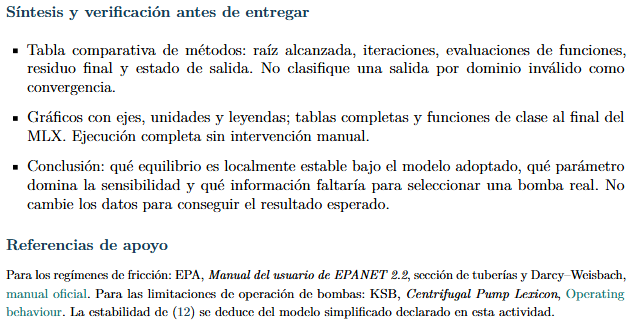

% SINTESIS Y VERIFICACION — tabla comparativa de los tres metodos
% ==================================================================
%  (va despues de h) y antes de la celda de funciones)
% ============================================================
% Reune los tres metodos. Una salida por dominio invalido NO se reporta
% como convergencia: aparece con su propio estado.

metodo = strings(0,1); semilla = strings(0,1); raizAlc = strings(0,1);
Qfinal = []; iters = []; evalsF = []; Rfinal = []; salida = strings(0,1);
internas = [];   % iteraciones internas de Colebrook acarreadas por el metodo

% --- Biseccion (inciso c) ---
for r = 1:2
    metodo(end+1,1)  = "Biseccion";
    semilla(end+1,1) = sprintf("[%.5f, %.5f]", intervalos(r,1), intervalos(r,2));
    raizAlc(end+1,1) = nombres(r);
    Qfinal(end+1,1)  = raiz_bis(r);
    iters(end+1,1)   = iter_bis(r);
    evalsF(end+1,1)  = evals_bis(r);
    Rfinal(end+1,1)  = Tbis{r}.R_m(end);
    internas(end+1,1)= sum(Tbis{r}.IterInternas);
    salida(end+1,1)  = estado_bis(r);
end

% --- Newton (inciso d) ---
for s = 1:2
    metodo(end+1,1)  = "Newton";
    semilla(end+1,1) = sprintf("(%.3f, %.3f)", semillas_N(s,1), semillas_N(s,2));
    [~, ir] = min(abs(raices_N(s,1) - raices(:,1)));
    if estado_N(s) == "convergio", raizAlc(end+1,1) = nombres(ir);
    else,                          raizAlc(end+1,1) = "ninguna"; end
    Qfinal(end+1,1) = raices_N(s,1);
    iters(end+1,1)  = iter_N(s);
    evalsF(end+1,1) = nF_N(s);
    Rfinal(end+1,1) = R_(raices_N(s,1), raices_N(s,2), P);
    internas(end+1,1) = 0;      % Newton resuelve (Q,f) a la vez: sin lazo interno
    salida(end+1,1) = estado_N(s);
end

% --- Punto fijo (inciso e; usa las variables ya calculadas alli) ---
for s = 1:numel(estado_pf)
    metodo(end+1,1)  = "Punto fijo";
    semilla(end+1,1) = sprintf("(%.3f, %.3f)", semillas_pf(s,1), semillas_pf(s,2));
    raizAlc(end+1,1) = destino_pf(s);
    Qfinal(end+1,1)  = Qfin_pf(s);
    iters(end+1,1)   = iter_pf(s);
    evalsF(end+1,1)  = 2*iter_pf(s);      % g1 y g2 por iteracion
    Rfinal(end+1,1)  = Rfin_pf(s);
    internas(end+1,1)= 0;       % g2 actualiza f directamente: sin lazo interno
    salida(end+1,1)  = estado_pf(s);
end

Tabla_comparativa_metodos = table(metodo, semilla, raizAlc, Qfinal, iters, evalsF, internas, Rfinal, salida, ...
    'VariableNames', {'Metodo','Semilla_o_Intervalo','Raiz_alcanzada','Q_final', ...
                      'Iteraciones','Eval_funcion','Iter_internas','Residuo_final','Estado_salida'})

fprintf(['\nCosto real: la biseccion necesita %d evaluaciones de F que arrastran\n' ...
         '%d iteraciones internas de Colebrook, frente a las %d evaluaciones de\n' ...
         'Newton sin lazo interno. Por eso las iteraciones externas no miden el costo.\n'], ...
        sum(evalsF(1:2)), sum(internas(1:2)), sum(evalsF(3:4)));

fprintf('\n--- Conclusiones ---\n');
fprintf('Equilibrio localmente estable: %s, con Q = %.6f m^3/s (F'' = %+.2f < 0).\n', ...
        nombres(Fp_g<0), Qg(Fp_g<0), Fp_g(Fp_g<0));
fprintf('Equilibrio inestable: %s, con Q = %.6f m^3/s (F'' = %+.2f > 0).\n', ...
        nombres(Fp_g>0), Qg(Fp_g>0), Fp_g(Fp_g>0));
fprintf('Parametro dominante en la sensibilidad: D, con %.1f%% y %.1f%% de la\n', ...
        100*c_D(1)/dQ_lin(1), 100*c_D(2)/dQ_lin(2));
fprintf('  desviacion lineal total en P1 y P2 respectivamente.\n');

% Conclusion:
% Bajo el modelo dinamico adoptado, el unico punto de operacion sostenible
% es P2 (mayor caudal), donde F'(Q) < 0. P1 satisface las ecuaciones pero
% es inestable, y ningun metodo iterativo lo "descarta" por eso: Newton lo
% alcanza sin dificultad desde una semilla cercana, mientras que el punto
% fijo no llega a el porque rho(JG) > 1. Son dos nociones de estabilidad
% distintas y no deben confundirse.
% El parametro dominante en la sensibilidad es el diametro D, que entra en
% cuatro dependencias del modelo; una tolerancia de fabricacion del 1% en D
% produce mas incertidumbre en el caudal que una variacion del 10% en la
% rugosidad.
% Para seleccionar una bomba real faltaria informacion que este modelo no
% contiene: margen de NPSH disponible frente al requerido (cavitacion),
% curva de eficiencia y potencia al eje en el punto de operacion, limites
% de caudal minimo y maximo continuo del fabricante, envejecimiento de la
% tuberia (eps crece con los anos y desplaza el punto de operacion), y el
% comportamiento en transitorios, que el modelo cuasiestacionario adoptado
% no describe.

Conclusión. Bajo el modelo dinámico adoptado, el único punto de operación sostenible es P2, el de mayor caudal, donde F'(Q) < 0. P1 satisface las ecuaciones pero es inestable, y ningún método iterativo lo descarta por ese motivo: Newton lo alcanza sin dificultad desde una semilla cercana, mientras que el punto fijo no llega a él porque ρ(JG) > 1. Son dos nociones de estabilidad distintas y no deben confundirse.

El parámetro dominante en la sensibilidad es el diámetro D, que interviene en cuatro dependencias del modelo; una tolerancia de fabricación del 1% en D produce más incertidumbre en el caudal que una variación del 10% en la rugosidad absoluta.

Para seleccionar una bomba real faltaría información que este modelo no contiene: el margen de NPSH disponible frente al requerido, para descartar cavitación; la curva de eficiencia y la potencia al eje en el punto de operación; los límites de caudal mínimo y máximo continuo indicados por el fabricante; el envejecimiento de la tubería, ya que ε crece con los años y desplaza el punto de operación; y el comportamiento en transitorios, que el modelo cuasiestacionario adoptado no describe.

Funciones empleadas (adjuntas al final del MLX, como exige la guía base).

% FUNCIONES — (A) funciones del laboratorio de clase, (B) rutinas del caso
% ==================================================================
%  Va como ULTIMA celda de codigo del MLX (lo exige la guia base:
%  "adjuntelas integramente al final del MLX").
%  Contiene:
%    (A) Funciones del laboratorio de clase, transcritas SIN cambios.
%    (B) Rutinas del caso, construidas sobre los algoritmos de clase
%        y adaptadas a los criterios (7)-(8) del enunciado.
% ============================================================


%% ---------- (A) FUNCIONES DE CLASE (Laboratorio S4) ----------
% Transcritas literalmente del material del curso. Se adjuntan por
% exigencia de la guia base. Observacion importante: ambas rutinas de
% Newton forman inv(J) de manera explicita y usan una norma infinito
% mezclada como criterio de parada. El enunciado de este RC pide lo
% contrario en los dos puntos (resolver J*s=-F sin invertir, y error
% relativo POR COMPONENTE con escalas Qs y fs), por lo que en el
% inciso d) se emplea la version adaptada newton_rc de la seccion (B).

function z = newton2v(F,x0,Tol)
    syms x y
    dF = jacobian(F(x,y),[x,y]);
    dF_fun = matlabFunction(dF);
    dr = 1;
    i = 0;
    z = [i x0' dr];
    while dr > Tol
        x1 = x0 - inv(dF_fun(x0(1),x0(2)))*F(x0(1),x0(2));
        dr = norm(x1 - x0,'inf')/norm(x1,'inf');
        x0 = x1;
        i = i + 1;
        z = [z; i x1' dr];
    end
end

function z = newtonVec(F,x0,Maxiter)
    n = length(x0);
    syms x [n 1]
    J_sym = jacobian(F(x),x);
    J = matlabFunction(J_sym, 'Vars',{x});
    error = NaN;
    z = [0 x0' error];
    for i = 1:Maxiter
        x1 = x0 - inv(J(x0))*F(x0);
        error = norm(x1 - x0,'inf')/norm(x1,'inf');
        x0 = x1;
        z = [z; i x1' error];
    end
end

function z = pfijos(G,x0,Tol)
    dr = 1;
    i = 0;
    z = [i x0' dr];
    while dr > Tol
        x1 = G(x0);
        dr = norm(x1-x0,'inf')/norm(x1,'inf');
        x0 = x1;
        i = i + 1;
        z = [z; i x1' dr];
    end
end


%% ---------- (B) RUTINAS DEL CASO ----------

% ----- Bloque basico del modelo -----

function r = Re_(Q,P)
    r = 4*Q./(pi*P.D*P.nu);
end

function A = A_(Q,f,P)
    A = P.eps/(3.7*P.D) + 2.51./(Re_(Q,P).*sqrt(f));
end

function B = B_(f,P)
    B = f*P.L/P.D + P.KT;
end

function v = N_(Q,P)
    v = P.H0 + P.a*Q - P.b*Q.^2 - P.dz;
end

function v = Hb_(Q,P)
    v = P.H0 + P.a*Q - P.b*Q.^2;
end

function v = Hs_(Q,f,P)
    v = P.dz + P.C*B_(f,P).*Q.^2;
end

function v = F1_(Q,f,P)
    v = N_(Q,P) - P.C*B_(f,P).*Q.^2;
end

function v = F2_(Q,f,P)
    v = 1./sqrt(f) + 2*log10(A_(Q,f,P));
end

function v = R_(Q,f,P)
    % Residuo adimensional, Ec. (8)
    v = max(abs(F1_(Q,f,P))/P.Href, abs(F2_(Q,f,P)));
end

function Jm = Jac_(Q,f,P)
    % Jacobiano analitico J = d(F1,F2)/d(Q,f), con la otra variable fija.
    t  = 2.51/(Re_(Q,P)*sqrt(f));
    A  = A_(Q,f,P);
    Jm = [ P.a - 2*P.b*Q - 2*P.C*B_(f,P)*Q ,  -P.C*(P.L/P.D)*Q^2 ; ...
           -2*t/(log(10)*Q*A)              ,  -0.5*f^(-3/2) - t/(log(10)*f*A) ];
end

function [ok,causa] = dominio_(Q,f,P)
    % Dominio real declarado: Q>0, f>0, Re>=4000, 0<A<1.
    ok = false;  causa = "-";
    if ~isfinite(Q) || ~isfinite(f), causa = "valor no finito";     return; end
    if ~(Q > 0),                     causa = "Q <= 0";              return; end
    if ~(f > 0),                     causa = "f <= 0";              return; end
    if Re_(Q,P) < 4000,              causa = "Re < 4000";           return; end
    A = A_(Q,f,P);
    if ~(A > 0 && A < 1),            causa = "A fuera de (0,1)";    return; end
    ok = true;
end

% ----- Iteracion interna: factor de friccion por punto fijo -----

function [f,it,ok,causa] = friccion_pf(Q,P,tol,maxit)
    % Resuelve Colebrook (Ec. 3) para Q fijo, por punto fijo
    % f_{k+1} = [-2 log10 A(Q,f_k)]^(-2), semilla 0.02.
    % Declara convergencia solo si el error relativo de f Y |F2| <= tol.
    f = 0.02;  it = 0;  ok = false;  causa = "-";
    if ~(Q > 0),          causa = "Q <= 0";     f = NaN;  return; end
    if Re_(Q,P) < 4000,   causa = "Re < 4000";  f = NaN;  return; end
    for k = 1:maxit
        A = A_(Q,f,P);
        if ~(A > 0 && A < 1)
            causa = "A fuera de (0,1)";  f = NaN;  it = k;  return;
        end
        fn = 1/(-2*log10(A))^2;
        er = abs(fn - f)/max(abs(fn), 1e-12*P.fs);
        f  = fn;  it = k;
        if er <= tol && abs(F2_(Q,f,P)) <= tol
            ok = true;  return;
        end
    end
    causa = "no converge en f";
end

function [Fq,f,itf,ok,causa] = Fesc_(Q,P,tol,maxit)
    % Funcion escalar F(Q) = F1(Q, f(Q)) de la Ec. (6).
    [f,itf,ok,causa] = friccion_pf(Q,P,tol,maxit);
    if ~ok,  Fq = NaN;  return;  end
    Fq = F1_(Q,f,P);
end

function v = Phi_(Q,P)
    % Altura estatica que hace F(Q)=0:  Phi(Q) = Hb(Q) - C*B(f(Q))*Q^2.
    % Como F(Q;dz) = Phi(Q) - dz, el barrido del inciso h) es invertir Phi.
    [f,~,ok,~] = friccion_pf(Q,P,1e-12,200);
    if ~ok,  v = NaN;  return;  end
    v = Hb_(Q,P) - P.C*B_(f,P)*Q^2;
end

function [Fp,fp] = dF_(Q,P)
    % Ec. (13):  f'(Q) = -F2_Q/F2_f ,  F'(Q) = F1_Q + F1_f*f'(Q).
    [f,~,ok,~] = friccion_pf(Q,P,1e-12,200);
    if ~ok,  Fp = NaN;  fp = NaN;  return;  end
    J  = Jac_(Q,f,P);
    fp = -J(2,1)/J(2,2);
    Fp = J(1,1) + J(1,2)*fp;
end

% ----- Derivadas respecto a los parametros (inciso f) -----

function d = dFdeps_(Q,f,P)
    % dF/d(eps) a Q,f constantes.  eps solo entra en A.
    A = A_(Q,f,P);
    d = [ 0 ; 2/(log(10)*A) * (1/(3.7*P.D)) ];
end

function d = dFdD_(Q,f,P)
    % dF/dD a Q,f constantes.  D entra en C (D^-4), en L/D, en eps/D y en Re.
    %   C*B = 8*f*L/(g*pi^2*D^5) + 8*KT/(g*pi^2*D^4)
    %   d(C*B)/dD = -40*f*L/(g*pi^2*D^6) - 32*KT/(g*pi^2*D^5)
    % y en F2, el termino 2.51/(Re*sqrt(f)) = 2.51*pi*D*nu/(4*Q*sqrt(f)) es
    % proporcional a D, de modo que d(t)/dD = t/D.
    A  = A_(Q,f,P);
    t  = 2.51/(Re_(Q,P)*sqrt(f));
    dF1 = Q^2*( 40*f*P.L/(P.g*pi^2*P.D^6) + 32*P.KT/(P.g*pi^2*P.D^5) );
    dF2 = 2/(log(10)*A) * ( -P.eps/(3.7*P.D^2) + t/P.D );
    d = [ dF1 ; dF2 ];
end

% ----- Biseccion (algoritmo de clase S3, criterios del enunciado) -----

function [raiz,T,salida,nEval] = biseccion_rc(l,u,P,tolE,tolR,N,verb)
    % Algoritmo de biseccion de S3 (Bolzano + division a la mitad),
    % con los criterios del enunciado:  E_k=(u-l)/(2|m|)<=tolE  y
    % |F(m)|/Href<=tolR.  La iteracion interna de f usa tol 1e-10.
    % Si una evaluacion de F falla, NO se usa para actualizar el intervalo.
    if nargin < 7, verb = true; end
    tolInt = 1e-10;  maxInt = 100;
    nEval  = 0;  raiz = NaN;  salida = "limite de iteraciones";
    datos  = zeros(0,9);

    [Fl,~,itl,okl] = Fesc_(l,P,tolInt,maxInt);  nEval = nEval + 1;
    [Fu,~,itu,oku] = Fesc_(u,P,tolInt,maxInt);  nEval = nEval + 1;
    if ~(okl && oku)
        salida = "dominio invalido en un extremo";
        T = array2table(datos,'VariableNames', ...
            {'k','l','u','m','f_m','F_m','E_k','R_m','IterInternas'});
        return
    end
    if Fl*Fu >= 0
        salida = "sin cambio de signo (Bolzano no se cumple)";
        T = array2table(datos,'VariableNames', ...
            {'k','l','u','m','f_m','F_m','E_k','R_m','IterInternas'});
        return
    end
    if verb
        fprintf('  Bolzano: F(%.6f) = %+.6e , F(%.6f) = %+.6e  ->  producto %+.3e < 0\n', ...
                l, Fl, u, Fu, Fl*Fu);
    end

    for k = 1:N
        m = (l+u)/2;
        [Fm,fm,itf,okm] = Fesc_(m,P,tolInt,maxInt);  nEval = nEval + 1;
        if ~okm
            salida = "dominio invalido en m";  break
        end
        Ek = (u-l)/(2*abs(m));
        Rm = abs(Fm)/P.Href;
        datos(end+1,:) = [k l u m fm Fm Ek Rm itf];   %#ok<AGROW>
        raiz = m;
        if Fm == 0
            salida = "raiz exacta";  break
        end
        if Ek <= tolE && Rm <= tolR
            salida = "convergio";  break
        end
        if Fl*Fm < 0
            u = m;
        else
            l = m;  Fl = Fm;
        end
    end
    T = array2table(datos,'VariableNames', ...
        {'k','l','u','m','f_m','F_m','E_k','R_m','IterInternas'});
end

% ----- Newton para el sistema acoplado (adaptado del laboratorio S4) -----

function [x,T,salida,nF,nJ] = newton_rc(x0,P,tole,tolR,Maxiter)
    % Adaptacion de newtonVec/newton2v del laboratorio S4 a lo que pide
    % este RC.  Tres cambios deliberados respecto de la version de clase:
    %   1) el paso se obtiene resolviendo  J(x_k) s_k = -F(x_k)  con el
    %      operador \ , sin formar inv(J);
    %   2) el Jacobiano es el analitico Jac_, no el simbolico;
    %   3) el criterio de parada es el (7)-(8) por componente, con las
    %      escalas Qs y fs, en lugar de la norma infinito mezclada.
    Q = x0(1);  f = x0(2);
    nF = 0;  nJ = 0;
    datos = zeros(0,5);
    salida = "limite de iteraciones";

    [ok,causa] = dominio_(Q,f,P);
    if ~ok
        salida = "dominio invalido en la semilla: " + causa;
        x = [Q;f];
        T = array2table(datos,'VariableNames',{'k','Q_k','f_k','e_k','R_k'});
        return
    end
    datos(end+1,:) = [0 Q f NaN R_(Q,f,P)];  nF = nF + 1;

    for k = 1:Maxiter
        Fv = [F1_(Q,f,P); F2_(Q,f,P)];  nF = nF + 1;
        J  = Jac_(Q,f,P);               nJ = nJ + 1;
        if rcond(J) < eps
            salida = "Jacobiano mal condicionado";  break
        end
        s  = J\(-Fv);                   % sin formar inv(J)
        Qn = Q + s(1);
        fn = f + s(2);

        [ok,causa] = dominio_(Qn,fn,P);
        if ~ok
            salida = "dominio invalido: " + causa;
            datos(end+1,:) = [k Qn fn NaN NaN];   %#ok<AGROW>
            break
        end

        ek = max( abs(Qn-Q)/max(abs(Qn),1e-12*P.Qs), ...
                  abs(fn-f)/max(abs(fn),1e-12*P.fs) );
        Q = Qn;  f = fn;
        Rk = R_(Q,f,P);  nF = nF + 1;
        datos(end+1,:) = [k Q f ek Rk];   %#ok<AGROW>

        if ek <= tole && Rk <= tolR
            salida = "convergio";  break
        end
    end
    x = [Q;f];
    T = array2table(datos,'VariableNames',{'k','Q_k','f_k','e_k','R_k'});
end